# PAH Moment Surface Gradients

clear; clc; close;

## Initialize User Deined Parameters

% Define airfoils of extreme cases full rigidity no aleviation and maximum
% camber. 
%   Currently I will be assuming a linear interpolation between the
%   extreme cases of airfoil deflection.
%   TODO: incorporate negative camber

% name of the file containing the horizontal tail effectivness
fileName_HorizontalTail_effectivness = "Archytas_horizontal_Tail_Effectiveness";

% name of airfoil files
fileName_maxCamber = "Selig 1223"; % filename of airfoil with the maximum camber
fileName_neutralCamber = "KL_sexy_sexy"; % filename of airfoil with the neutral camber

% wing-fuselage parameters
S = 13.27; % wing planform area (m^2)
c_bar = .772; % mean geometric cord of the wing
C_L_alpha_wf_maxCamber = .484; % lift curve slope of horizontal wing-fuselage per radian
C_L_alpha_wf_neutralCamber = .484; % lift curve slope of horizontal wing-fuselage per radian
%C_L_0_wf = 0; % coefficient of wing-fuselage lift at zero angle of attack
C_m_0_wf = .140; % coefficient of wing-fuselage moment at zero angle of attack from AVL

% horizontal tail parameters
S_h = 1.75; % horizontal tail planform area (m^2)
C_L_alpha_h = .484; % lift curve slope of horizontal tail per radian
C_L_0_h = 0; % coefficient of tail lift at zero angle of attack
C_m_0_h = 0; % coefficient of tail moment at zero angle of attack
d_epsilon_h_d_alpha = .111; % downwash gradient on horizontal tail (~) from AAA (can also compute using roskam part 6 page 262)
epsilon_0_h = 0; % aproximately true for flaps up configuration TODO: investigate later
i_h = -2.5; % -2.5 timed for no PAH, -12.4 for 1.5 relaxation PAH

% cambers
camber_neutral = .03767;
camber_max = .81;

% location parameters
x_bar_cg = .1217; % cg location in terms of wing mean geometric cords
x_bar_ac_h = 8.19; % horizontal tail aerodynamic center location in terms of wing mean geometric cords
x_bar_ac_wf = .185; % wing-fuselage aerodynamic center location in terms of wing mean geometric cords

% Meshing Parameters
% store the plot points as an array
nPlotPoints_linearRegion = 10*4; % number of plot points in the linear region
nPlotPoints_NLPreStall = 5*4; % number of plot points in the Nonlinear prestall Region
nPlotPoints_NLPostStall = 2*4; % number of plot points in the Nonlinear poststall Region
n_plotPoints_momentCurve = [nPlotPoints_linearRegion, nPlotPoints_NLPreStall, nPlotPoints_NLPostStall];
n_alphaPoints_momentCurve = sum(n_plotPoints_momentCurve);

n_InermediateCambers = 10;
nSlicePoints = 100;

% plotting parameters
alphas_plot = deg2rad(linspace(-10,23,n_alphaPoints_momentCurve));

% animation parameters
n_frames_animate = 10;
n_frames_animate = 2;

## Initialize Variables

% load the horizontal tail effectivness
load(fileName_HorizontalTail_effectivness)
hTailEffecitvenessData = [deg2rad(alphas), eta_h];
hTailEffecitvenessData = hTailEffecitvenessData(1:end-1,:); % in this data the last point is bad
load('Archytas_eta_h_function.mat'); % this is the way to generate the funciton

% Load airfoils
airfoil_maxCamber = ReadAirfoil(fileName_maxCamber);
airfoil_neutralCamber = ReadAirfoil(fileName_neutralCamber);

## Determine a function for horizontal tail effectivness 

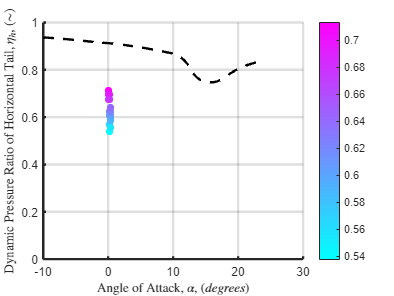

% try agian this time with colour gradient
figure
patch(deg2rad(alphas), eta_h, eta_h,'EdgeColor','none','Marker','o','MarkerFaceColor','flat', "LineWidth", 2); colormap cool
colorbar;
ylabel("Dynamic Pressure Ratio of Horizontal Tail, $\eta_h$, $(\sim)$","Interpreter","latex");
xlabel("Angle of Attack, $\alpha$, $(degrees)$","Interpreter","latex");
grid on;
ylim([0,1])
set(gca,"LineWidth", 2);

%produce a function to generate eta_h as a function of angle of attack
% assume the horizontal tail effectivness is constant for negative angles of attack
eta_h_plot = get_eta_h(alphas_plot, eta_FuncOf_alpha);

hold on
plot(rad2deg(alphas_plot), eta_h_plot, "--k", "LineWidth", 2)

## Compute Moments

%%%%%%%%%%%%%%%%%%%%%%%%
% horizontal tail moment
%%%%%%%%%%%%%%%%%%%%%%%%
% horizontal tail coefficient of moment due to angle of attack
C_m_alpha_h = PitchMomentCoefficient_withRespectTo_Alpha_horizontalTail(S_h, eta_h_plot, C_L_alpha_h, d_epsilon_h_d_alpha, x_bar_cg, x_bar_ac_h, S);
% horizontal tail coefficient of moment due at 0 angle of attack
C_m_0_h = PitchMomentCoefficient_zeroAoA_horizontalTail(S_h, get_eta_h(0,eta_FuncOf_alpha), C_L_alpha_h, epsilon_0_h, x_bar_cg, x_bar_ac_h, S)

C_m_0_h = 0

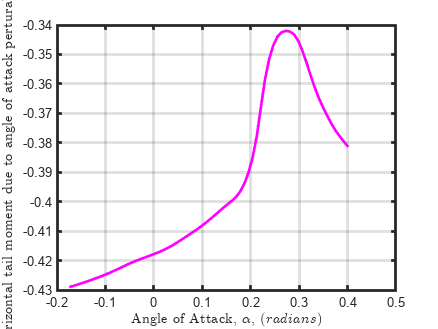

% horizontal tail coefficient of moment due to horizontal tail incidence
C_m_ih = PitchMomentCoefficient_withRespectTo_horizontalTailIncidence(S_h, eta_h_plot, C_L_alpha_h, x_bar_cg, x_bar_ac_h, S);
figure
plot(alphas_plot, C_m_alpha_h, "m", "LineWidth", 2);
grid on;
set(gca,"LineWidth", 2);

ylabel("Coeffcient of horizontal tail moment due to angle of attack perturabtion, $C_{m_{alpha_{h}}}$, $(\sim)$","Interpreter","latex");
xlabel("Angle of Attack, $\alpha$, $(radians)$","Interpreter","latex");

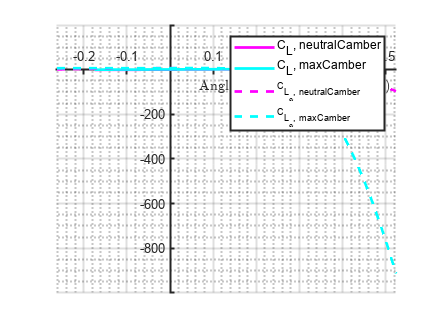




%%%%%%%%%%%%%%%%%%%%%%%%
% wing moment
%%%%%%%%%%%%%%%%%%%%%%%%

% demonstrate ability to generate C_L_alpha and C_L
alpha = deg2rad(linspace(-15,30,n_alphaPoints_momentCurve));

% plot C_l
figure; hold on;
% compute C_l
C_l_neutralCamber = airfoil_neutralCamber.get_C_l(alphas_plot); % I shoud check if the hard clamp to zero is appropriate
C_l_maxCamber = airfoil_maxCamber.get_C_l(alphas_plot); % I shoud check if the hard clamp to zero is appropriate
% plot the computed values
plot(alphas_plot, C_l_neutralCamber, "-m", "LineWidth",2, "DisplayName","C_L, neutralCamber");
plot(alphas_plot, C_l_maxCamber, "-c", "LineWidth",2, "DisplayName","C_L, maxCamber");

% plot C_l_alpha
hold on 
fplot(@(alpha) airfoil_neutralCamber.get_C_l_alpha(alpha), "--m", "LineWidth",2, "DisplayName","C_{L_\alpha, neutralCamber}")
fplot(@(alpha) airfoil_maxCamber.get_C_l_alpha(alpha), "--c", "LineWidth",2, "DisplayName","C_{L_\alpha, maxCamber}")
xlim(deg2rad([-15,30]))
xlabel("Angle of Attack, $\alpha$, $(radians)$","Interpreter","latex");
set(gca,"LineWidth", 1.5);
legend;
grid(gca,'on'); hold(gca,'off'); set(gca,'LineWidth',1.5,'XAxisLocation','origin', 'YAxisLocation','origin', 'XMinorGrid','on','YMinorGrid','on','ZMinorGrid', 'on');

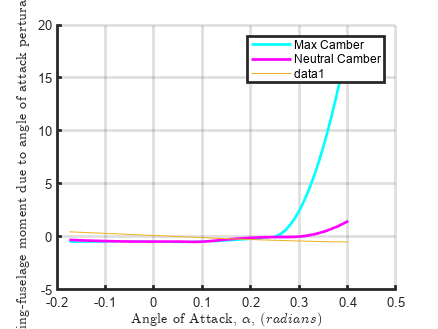


% compute C_L_alpha of the wing
% assume for simplicity that C_L_alpha = C_l_alpha
C_L_alpha_wf_maxCamber = arrayfun(@(alpha) airfoil_maxCamber.get_C_l_alpha(alpha), alphas_plot);
C_L_alpha_wf_neutralCamber = arrayfun(@(alpha) airfoil_neutralCamber.get_C_l_alpha(alpha), alphas_plot);
% also assume C_L = c_l
C_L_maxCamber = C_l_maxCamber;
C_L_neutralCamber = C_l_neutralCamber;

% compute wing c_m_alpha

C_m_alpha_wf_maxCamber = PitchMomentCoefficient_withRespectTo_Alpha_wingFueslage(C_L_alpha_wf_maxCamber, x_bar_cg, x_bar_ac_wf);
C_m_alpha_wf_neutralCamber = PitchMomentCoefficient_withRespectTo_Alpha_wingFueslage(C_L_alpha_wf_neutralCamber, x_bar_cg, x_bar_ac_wf);

% compute the wing moment coefficent
c_m_wf_maxCamber = C_m_0_wf + arrayfun(@(alpha) integral(@(a) airfoil_maxCamber.get_C_l_alpha(a), 0, alpha), alphas_plot);
C_m_neutralCamber = C_m_0_wf + arrayfun(@(alpha) integral(@(a) airfoil_neutralCamber.get_C_l_alpha(a), 0, alpha), alphas_plot);

% plot the wing c_m_alpha
figure; hold on
plot(alphas_plot, C_m_alpha_wf_maxCamber, "-c", "LineWidth",2, "DisplayName","Max Camber");
plot(alphas_plot, C_m_alpha_wf_neutralCamber, "-m", "LineWidth",2, "DisplayName","Neutral Camber");
legend; grid on
set(gca,"LineWidth", 2); %set(gca, "XAxisLocation", "origin", "YAxisLocation","origin");
ylabel("Coeffcient of wing-fuselage moment due to angle of attack perturabtion, $C_{m_{\alpha_{wf}}}$, $(\sim)$","Interpreter","latex");
xlabel("Angle of Attack, $\alpha$, $(radians)$","Interpreter","latex");


%%%%%%%%%%%%%%%%%%%%%%%%
% fuselage moment
%%%%%%%%%%%%%%%%%%%%%%%%

% compute c_m_alpha
C_m_alpha_maxCamber = C_m_alpha_wf_maxCamber + C_m_alpha_h;
C_m_alpha_neutralCamber = C_m_alpha_wf_neutralCamber + C_m_alpha_h;

%  compute static margin
SM_maxCamber = -C_m_alpha_maxCamber ./ C_L_alpha_wf_maxCamber;
SM_neutralCamber = -C_m_alpha_neutralCamber ./ C_L_alpha_wf_neutralCamber;

% compute the aircraft moment coefficient
C_m_maxCamber = PitchingMomentCoeffcient(alphas_plot, i_h, C_m_0_wf, C_m_0_h, airfoil_maxCamber, C_L_alpha_h, x_bar_cg, x_bar_ac_wf, x_bar_ac_h, S_h, S, eta_FuncOf_alpha, d_epsilon_h_d_alpha);
C_m_neutralCamber = PitchingMomentCoeffcient(alphas_plot, i_h, C_m_0_wf, C_m_0_h, airfoil_neutralCamber, C_L_alpha_h, x_bar_cg, x_bar_ac_wf, x_bar_ac_h, S_h, S, eta_FuncOf_alpha, d_epsilon_h_d_alpha);
plot(alphas_plot, C_m_neutralCamber);

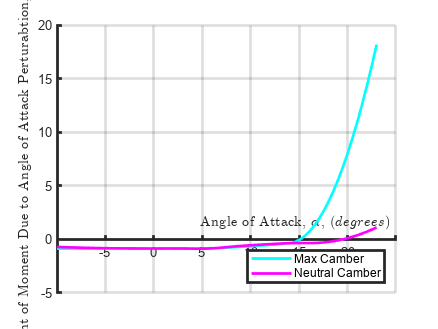



% beigin plotting

% plot c_m_alpha
figure; hold on
plot(rad2deg(alphas_plot), C_m_alpha_maxCamber, "-c", "LineWidth",2, "DisplayName","Max Camber");
plot(rad2deg(alphas_plot), C_m_alpha_neutralCamber, "-m", "LineWidth",2, "DisplayName","Neutral Camber");
legend("Location","southeast"); grid on
set(gca,"LineWidth", 2); set(gca, "XAxisLocation", "origin"); %set(gca, "XAxisLocation", "origin", "YAxisLocation","origin");
ylabel("Coeffcient of Moment Due to Angle of Attack Perturabtion, $C_{m_{\alpha}}$, $(\sim)$","Interpreter","latex");
xlabel("Angle of Attack, $\alpha$, $(degrees)$","Interpreter","latex");

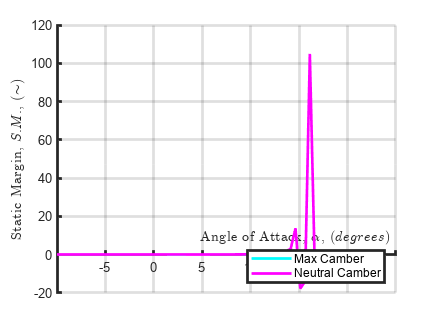


% plot static margin
figure; hold on
plot(rad2deg(alphas_plot), SM_maxCamber, "-c", "LineWidth",2, "DisplayName","Max Camber");
plot(rad2deg(alphas_plot), SM_neutralCamber, "-m", "LineWidth",2, "DisplayName","Neutral Camber");
legend("Location","southeast"); grid on
set(gca,"LineWidth", 2); set(gca, "XAxisLocation", "origin"); %set(gca, "XAxisLocation", "origin", "YAxisLocation","origin");
ylabel("Static Margin, $S.M.$, $(\sim)$","Interpreter","latex");
xlabel("Angle of Attack, $\alpha$, $(degrees)$","Interpreter","latex");

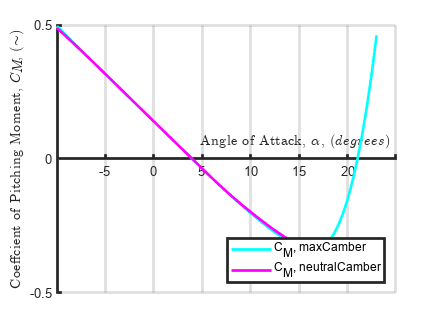


% plot c_m
figure; hold on
plot(rad2deg(alphas_plot), C_m_maxCamber, "-c", "LineWidth",2, "DisplayName","C_M, maxCamber");
plot(rad2deg(alphas_plot), C_m_neutralCamber, "-m", "LineWidth",2, "DisplayName","C_M, neutralCamber");
legend("Location","southeast"); grid on
set(gca,"LineWidth", 2); set(gca, "XAxisLocation", "origin"); %set(gca, "YAxisLocation","origin");
ylabel("Coeffcient of Pitching Moment, $C_{M}$, $(\sim)$","Interpreter","latex");
xlabel("Angle of Attack, $\alpha$, $(degrees)$","Interpreter","latex");

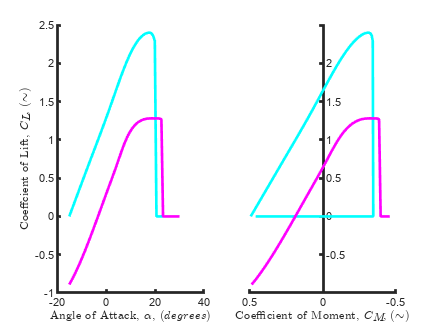


%plot(rad2deg(alphas_plot), C_l_maxCamber, "--c", "LineWidth",2, "DisplayName","C_L, maxCamber");
%plot(rad2deg(alphas_plot), C_l_neutralCamber, "--m", "LineWidth",2, "DisplayName","C_L, neutralCamber");


% plot trim diagram
figure;
% Lift Coeffcient versus angle of attack
ax1 = subplot(1,2,1);
hold on;
plot(rad2deg(alpha), C_L_maxCamber, "-c", "LineWidth",2, "DisplayName","Max Camber");
plot(rad2deg(alpha), C_L_neutralCamber, "-m", "LineWidth",2, "DisplayName","Neutral Camber");
xlabel("Angle of Attack, $\alpha$, $(degrees)$","Interpreter","latex");
ylabel("Coeffcient of Lift, $C_{L}$, $(\sim)$","Interpreter","latex");
set(gca,"LineWidth",2);
% Lift Coeffcient versus Moment Coeffcient
ax2 = subplot(1,2,2);
hold on;
plot(C_m_maxCamber, C_L_maxCamber, "-c", "LineWidth",2, "DisplayName","Max Camber");
plot(C_m_neutralCamber, C_L_neutralCamber, "-m", "LineWidth",2, "DisplayName","Neutral Camber");
set(gca, "YAxisLocation","origin"); set(gca,'XDir','rev');
xlabel("Coefficient of Moment, $C_M$, $(\sim)$","Interpreter","latex");
% relate the two plots
linkaxes([ax1, ax2], 'y');
set(gca,"LineWidth",2);

## Meshing Moment Lines

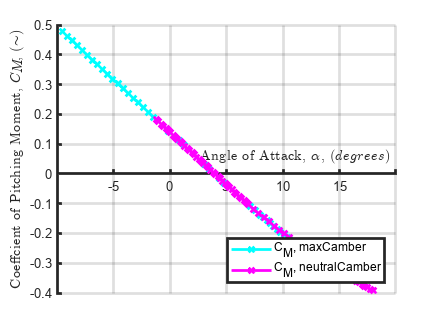

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pitch Moment Curves meshing
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% get the points to define point spacing in the mesh
[alphas_maxCamber, c_ls_maxCamber] = airfoil_maxCamber.getPlotPoints;
[alphas_neutralCamber, c_ls_neutralCamber] = airfoil_neutralCamber.getPlotPoints;


% initialize loop variables meshes
regionIndex = 1;
alphas_maxCamber_interped = zeros(n_alphaPoints_momentCurve,1);
alphas_neutralCamber_interped = zeros(n_alphaPoints_momentCurve,1);

% there may be an inconsitent assumetion in here with the C_L i use to
% calculate C_M not being interpolated from the C_L cuves.

% Note I am possibly currently duplicating point on segment transitions but is isn't
% currently affecting 
alphas_maxCamber_interped(1) = alphas_maxCamber(1);
alphas_neutralCamber_interped(1) = alphas_neutralCamber(1);
for i = 1:3
    n_plotPoints_region = n_plotPoints_momentCurve(i); % determine number of alpha in this mesh segment

    % linterp alphas
    alphas_maxCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = linspace(alphas_maxCamber(i), alphas_maxCamber(i+1), n_plotPoints_region);
    alphas_neutralCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = linspace(alphas_neutralCamber(i), alphas_neutralCamber(i+1), n_plotPoints_region);

    alph_mc = linspace(alphas_maxCamber(i), alphas_maxCamber(i+1), n_plotPoints_region+1);
    alph_nc = linspace(alphas_neutralCamber(i), alphas_neutralCamber(i+1), n_plotPoints_region+1);
    alphas_maxCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = alph_mc(2:end);
    alphas_neutralCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = alph_nc(2:end);
    
    % linterp cl's
    c_ls_mc = linspace(c_ls_maxCamber(i), c_ls_maxCamber(i+1), n_plotPoints_region+1);
    c_ls_nc = linspace(c_ls_neutralCamber(i), c_ls_neutralCamber(i+1), n_plotPoints_region+1);

    % produce the smoothed cl's
    spl_MC = CL_alpha_Smooother([alphas_maxCamber', c_ls_maxCamber'], 0, 2);
    c_ls_mc = fnval(spl_MC,alph_mc);
    spl_NC = CL_alpha_Smooother([alphas_neutralCamber', c_ls_neutralCamber'], 0, 2);
    c_ls_nc = fnval(spl_NC,alph_nc);

    c_ls_maxCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = c_ls_mc(2:end);
    c_ls_neutralCamber_interped(regionIndex:regionIndex+n_plotPoints_region-1) = c_ls_nc(2:end);

    % update index of access into array
    regionIndex = regionIndex + n_plotPoints_region;
end

% produce C_L's
C_L_maxCamber = c_ls_maxCamber_interped;
C_L_neutralCamber = c_ls_neutralCamber_interped;
% this produces a dlightly diffrent result 
%C_L_maxCamber = arrayfun(@(alpha)airfoil_maxCamber.get_C_l(alpha), alphas_maxCamber_interped); % this produces a slightly diffrent result but is safe to use
%C_L_neutralCamber = arrayfun(@(alpha)airfoil_neutralCamber.get_C_l(alpha), alphas_neutralCamber_interped); % this produces a slightly diffrent result but is safe to use


% produce C_M's
C_m_maxCamber = PitchingMomentCoeffcient(alphas_maxCamber_interped, i_h, C_m_0_wf, C_m_0_h, airfoil_maxCamber, C_L_alpha_h, x_bar_cg, x_bar_ac_wf, x_bar_ac_h, S_h, S, eta_FuncOf_alpha, d_epsilon_h_d_alpha);
C_m_neutralCamber = PitchingMomentCoeffcient(alphas_neutralCamber_interped, i_h, C_m_0_wf, C_m_0_h, airfoil_neutralCamber, C_L_alpha_h, x_bar_cg, x_bar_ac_wf, x_bar_ac_h, S_h, S, eta_FuncOf_alpha, d_epsilon_h_d_alpha);


% plot c_m
figure; hold on
plot(rad2deg(alphas_maxCamber_interped), C_m_maxCamber, "-xc", "LineWidth",2, "DisplayName","C_M, maxCamber");
plot(rad2deg(alphas_neutralCamber_interped), C_m_neutralCamber, "-xm", "LineWidth",2, "DisplayName","C_M, neutralCamber");
legend("Location","southeast"); grid on
set(gca,"LineWidth", 2); set(gca, "XAxisLocation", "origin"); %set(gca, "YAxisLocation","origin");
ylabel("Coeffcient of Pitching Moment, $C_{M}$, $(\sim)$","Interpreter","latex");
xlabel("Angle of Attack, $\alpha$, $(degrees)$","Interpreter","latex");


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Interior Curves
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% camber index will be defined with 0 being the camber of neutrally camber
% airfoil and nCIntermediateCamber being the index of the maximum camber
% airfoil.

% alpha index will be defined with 0 being the zero lift alpha (alpha_0)
% and n_alphaPoints_momentCurve being the index of alpha_post_stall

%   alpha             =   Lift_surface_mesh(alphaIndex, camberIndex, 1)
%   camberParameter   =   Lift_surface_mesh(alphaIndex, camberIndex, 2)
%   C_L               =   Lift_surface_mesh(alphaIndex, camberIndex, 3)

% mesh between them
%generate the intermediate C_m's

% ther is a possible work where the mesh has differnt alphas that dont
% match up
alpha_coords_maxCamber = alphas_maxCamber_interped;
alpha_coords_neutralCamber = alphas_neutralCamber_interped;


%
C_m_intermediate = C_m_neutralCamber;

for  alpha_index = 1:n_alphaPoints_momentCurve
    alpha_coords(alpha_index,:) = linspace(alpha_coords_neutralCamber(alpha_index), alpha_coords_maxCamber(alpha_index), n_InermediateCambers);
    camber_coords(alpha_index,:) = linspace(camber_neutral, camber_max, n_InermediateCambers);
    C_M_coords(alpha_index,:) = linspace(C_m_neutralCamber(alpha_index), C_m_maxCamber(alpha_index), n_InermediateCambers);
    C_L_coords(alpha_index,:) = linspace(C_L_neutralCamber(alpha_index), C_L_maxCamber(alpha_index), n_InermediateCambers);
end

Moment_surface_mesh(:,:,1) = alpha_coords;
Moment_surface_mesh(:,:,2) = camber_coords;
Moment_surface_mesh(:,:,3) = C_M_coords;
Moment_surface_mesh(:,:,4) = C_L_coords;

## Plot Moment Surface

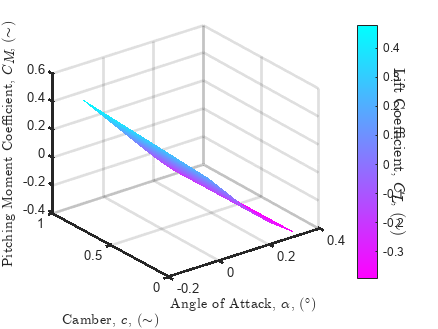

% wireframe mesh
figure;
mesh(Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3),"FaceAlpha",.5);
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Pitching Moment Coefficient, $C_M$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);

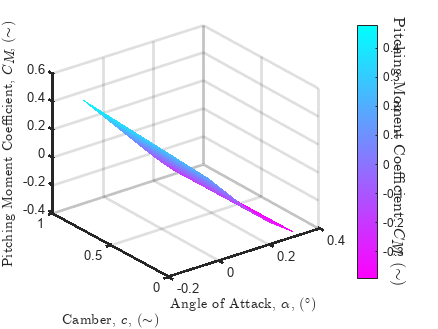


% colourful wire frame
figure;
s = mesh(Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), "FaceAlpha",.5);
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Pitching Moment Coefficient, $C_M$, $(\sim)$", "Interpreter","latex");
s.FaceColor = 'interp'; % colour the segments
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);
cb = colorbar; ylabel(cb,'Pitching Moment Coefficient, $C_M$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);

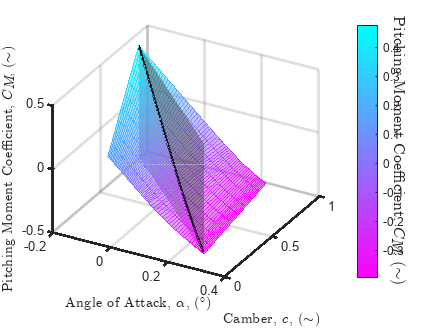


% surface
figure;
surf(Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), "FaceAlpha",.5, "EdgeColor","interp");
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Pitching Moment Coefficient, $C_M$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Pitching Moment Coefficient, $C_M$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);
view([28.657753011414982,36.019743806946884]);

% slice plane
% cover all the alphas an cl_s
[alpha_slice, C_M_slice] = meshgrid(linspace(min(Moment_surface_mesh(:,:,1),[],"all"), max(Moment_surface_mesh(:,:,1),[],"all"), nSlicePoints), linspace(min(Moment_surface_mesh(:,:,3),[],"all"), max(Moment_surface_mesh(:,:,3),[],"all"), nSlicePoints));

camber_max = max(Moment_surface_mesh(:,:,2),[],"all");
camber_min = min(Moment_surface_mesh(:,:,2),[],"all");
alpha_max = max(Moment_surface_mesh(:,:,1),[],"all");
alpha_min = min(Moment_surface_mesh(:,:,1),[],"all");
camber_slice = camber_max - (camber_max - camber_min) / (alpha_max-alpha_min) * (alpha_slice - alpha_min);

hold on
slicePlane = mesh(alpha_slice, camber_slice, C_M_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[.3,.3,.3]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_m_intercept] = griddata(Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), alpha_slice,camber_slice);
plot3(alpha_intercept(1,:), camber_intercept(1,:), c_m_intercept(1,:), "-k", "LineWidth",2);

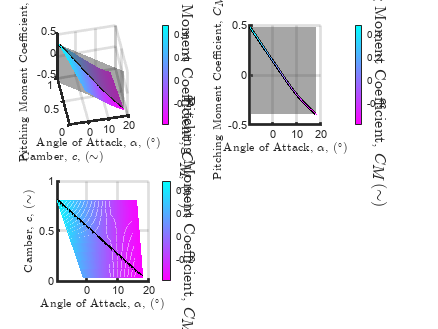

set(gca,"LineWidth",2);

% spoof the subplot figure i want to see
figure;

% trimetric(ish) view
subplot(2,2,1);
s = mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), "FaceAlpha",.5);
s.FaceColor = 'interp';
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Pitching Moment Coefficient, $C_M$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Pitching Moment Coefficient, $C_M$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
hold on;
slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_M_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[.3,.3,.3]);
view([-12.08 47.25]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_m_intercept] = griddata(Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), alpha_slice,camber_slice);
plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_m_intercept(1,:), "-k", "LineWidth",2);
set(gca,"LineWidth",2);

% side view
subplot(2,2,2);
s = mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), "FaceAlpha",.5);
s.FaceColor = 'interp';
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Pitching Moment Coefficient, $C_M$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Pitching Moment Coefficient, $C_M$ $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
hold on
slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_M_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[.3,.3,.3]);
view([0,0]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_m_intercept] = griddata(Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), alpha_slice,camber_slice);
plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_m_intercept(1,:), "-k", "LineWidth",2);
set(gca,"LineWidth",2);

% top view
subplot(2,2,3);
s = mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), "FaceAlpha",.5);
s.FaceColor = 'interp';
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Pitching Moment Coefficient, $C_M$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Pitching Moment Coefficient, $C_M$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
hold on
slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_M_slice, "FaceAlpha",1, "EdgeColor","none", "FaceColor",[.3,.3,.3], "LineWidth",2);
view([0,90]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_m_intercept] = griddata(Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,3), alpha_slice,camber_slice);
plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_m_intercept(1,:), "-k", "LineWidth",2);
set(gca,"LineWidth",2);

## Plot lift surface

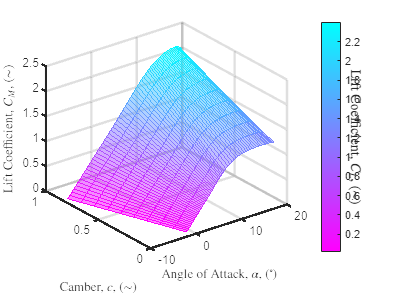

% wireframe mesh
figure;
mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), "FaceAlpha",.5 , "FaceColor", "interp");
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $C_M$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);

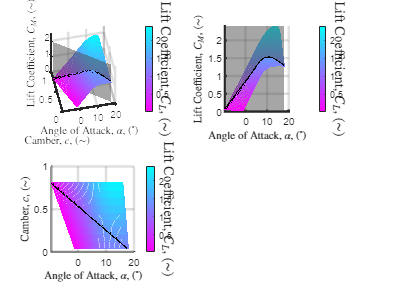


% spoof the subplot figure i want to see
figure;

[alpha_slice, C_L_slice] = meshgrid(linspace(min(Moment_surface_mesh(:,:,1),[],"all"), max(Moment_surface_mesh(:,:,1),[],"all"), nSlicePoints), linspace(min(Moment_surface_mesh(:,:,4),[],"all"), max(Moment_surface_mesh(:,:,4),[],"all"), nSlicePoints));
% trimetric(ish) view
subplot(2,2,1);
s = mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), "FaceAlpha",.5);
s.FaceColor = 'interp';
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $C_M$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
hold on
slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[.3,.3,.3]);
view([-12.08 47.25]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_m_intercept] = griddata(Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), alpha_slice,camber_slice);
plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_m_intercept(1,:), "-k", "LineWidth",2);
set(gca,"LineWidth",2);

% side view
subplot(2,2,2);
s = mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), "FaceAlpha",.5);
s.FaceColor = 'interp';
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $C_M$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
hold on
slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[.3,.3,.3]);
view([0,0]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_m_intercept] = griddata(Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), alpha_slice,camber_slice);
plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_m_intercept(1,:), "-k", "LineWidth",2);
set(gca,"LineWidth",2);

% top view
subplot(2,2,3);
s = mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), "FaceAlpha",.5);
s.FaceColor = 'interp';
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $C_L$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
hold on
slicePlane = mesh(rad2deg(alpha_slice), camber_slice, C_L_slice, "FaceAlpha",1, "EdgeColor","none", "FaceColor",[.3,.3,.3], "LineWidth",2);
view([0,90]);
% highlight the intersection
[alpha_intercept, camber_intercept, c_m_intercept] = griddata(Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), alpha_slice,camber_slice);
plot3(rad2deg(alpha_intercept(1,:)), camber_intercept(1,:), c_m_intercept(1,:), "-k", "LineWidth",2);
set(gca,"LineWidth",2);

## Compute Lift and Moment Surface Gradients

C_L = Moment_surface_mesh(:,:,4);
alphaMesh = Moment_surface_mesh(:,:,1);
camberMesh = Moment_surface_mesh(:,:,2);
surfaceMesh(:,:,1) = Moment_surface_mesh(:,:,1);
surfaceMesh(:,:,2) = Moment_surface_mesh(:,:,2);

% compute the graident of lift and moment
[C_L_alpha, C_L_camber] = MeshGradient(Moment_surface_mesh(:,:,4), Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2));
[C_M_alpha, C_M_camber] = MeshGradient(Moment_surface_mesh(:,:,3), Moment_surface_mesh(:,:,1), Moment_surface_mesh(:,:,2));

## Plot the lift surface gradient components

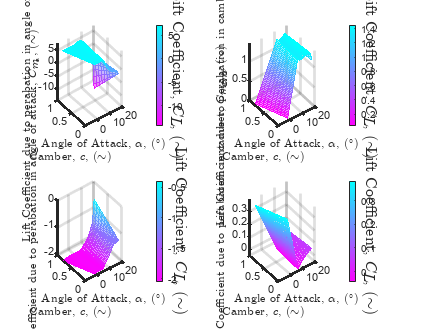

figure
% Lift coefficient gradients
subplot(2,2,1) % with respect to alpha
mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), C_L_alpha, "FaceAlpha",.5 , "FaceColor", "interp");
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient due to perabation in angle of attack, $C_{L_{\alpha}}$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);
subplot(2,2,2) % with respect to camber
mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), C_L_camber, "FaceAlpha",.5 , "FaceColor", "interp");
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient due to perabation in camber, $C_{L_{camb}}$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);
%moment coefficient graidents
subplot(2,2,3) % with respect to alpha
mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), C_M_alpha, "FaceAlpha",.5 , "FaceColor", "interp");
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Pitch Moment Coefficient due to perabation in angle of attack, $C_{m_{\alpha}}$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);
subplot(2,2,4) % with respect to camber
mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), C_M_camber, "FaceAlpha",.5 , "FaceColor", "interp");
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Pitch Moment Coefficient due to perabation in camber, $C_{m_{camb}}$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);


% 3D trim diagram
figure;

% Lift coefficient vs alpha
ax1 = subplot(1,2,1);
mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), "FaceAlpha",.5 , "FaceColor", "interp");
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $C_M$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);

% Lift coefficient vs Moment coefficient
ax2 = subplot(1,2,2);
mesh(rad2deg(Moment_surface_mesh(:,:,3)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), "FaceAlpha",.5 , "FaceColor", "interp");
xlabel("Pitch Moment Coefficient, $C_M$, $(\sim)$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient, $C_L$, $(\sim)$", "Interpreter","latex");
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
linkaxes([ax1, ax2], 'yz');
set(gca,'XDir','rev');
set(gca,"LineWidth",2);


hold on
Delta_C_M_ih = C_m_ih % for now assume linear ignore horizontal tail blanking

Delta_C_M_ih =     0.4826    0.4821    0.4816    0.4811    0.4806    0.4800    0.4794    0.4788    0.4782    0.4776    0.4769    0.4762    0.4754    0.4747    0.4739    0.4732    0.4726    0.4719    0.4714    0.4708    0.4702    0.4696    0.4689    0.4682    0.4673    0.4664    0.4654    0.4644    0.4633    0.4623    0.4612    0.4601    0.4590    0.4577    0.4564    0.4550    0.4536    0.4523    0.4509    0.4497    0.4482    0.4462    0.4432    0.4390    0.4332    0.4252    0.4140    0.4032    0.3955    0.3902


p_ih = deg2rad(20);
m_ih = deg2rad(-20);
c_m_p_ih = arrayfun(@(alpha) integral(@(ih) arrayfun(@(i) PitchMomentCoefficient_withRespectTo_horizontalTailIncidence(S_h, get_eta_h(alpha, eta_FuncOf_alpha), C_L_alpha_h, x_bar_cg, x_bar_ac_h, S), ih), 0, p_ih), Moment_surface_mesh(:,1,1))

c_m_p_ih =     0.1646
    0.1645
    0.1644
    0.1643
    0.1642
    0.1641
    0.1640
    0.1639
    0.1638
    0.1637


c_m_m_ih = arrayfun(@(alpha) integral(@(ih) arrayfun(@(i) PitchMomentCoefficient_withRespectTo_horizontalTailIncidence(S_h, get_eta_h(alpha, eta_FuncOf_alpha), C_L_alpha_h, x_bar_cg, x_bar_ac_h, S), ih), 0, m_ih), Moment_surface_mesh(:,1,1))

c_m_m_ih =    -0.1646
   -0.1645
   -0.1644
   -0.1643
   -0.1642
   -0.1641
   -0.1640
   -0.1639
   -0.1638
   -0.1637


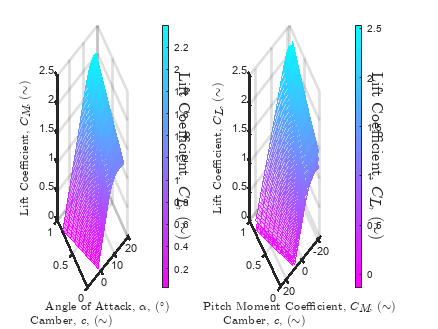

%c_L_p_ih = arrayfun(@(alpha) integral(@(alpha) arrayfun(@(i) (S_h/S*get_eta_h(alpha, eta_FuncOf_alpha))* C_L_alpha_h, 0, p_ih), 0, alpha), Moment_surface_mesh(:,1,1))

mesh(rad2deg(Moment_surface_mesh(:,:,3)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4) +  c_m_p_ih, "FaceAlpha",.5);
mesh(rad2deg(Moment_surface_mesh(:,:,3)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4) +  c_m_m_ih, "FaceAlpha",.5);
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);

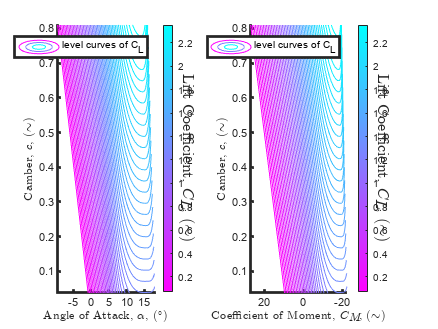

set(gca,"LineWidth",2);

% gradient
alpha_max_trim = deg2rad(6);
alpha_min_trim = deg2rad(4.5);
alpha_filter_tirm = Moment_surface_mesh(:,1,1) >= alpha_max_trim | Moment_surface_mesh(:,1,1) <= alpha_min_trim;

figure;
subplot(1,2,1); % Lift coefficient gradients
hold on;
contour(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), 50)
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient due to perabation in angle of attack, $C_{L_{\alpha}}$, $(\sim)$", "Interpreter","latex")
legend("level curves of C_L")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);

subplot(1,2,2); % Moment coefficient gradients
hold on;
%contour(rad2deg(Moment_surface_mesh(alpha_filter_tirm,:,1)), Moment_surface_mesh(alpha_filter_tirm,:,2), Moment_surface_mesh(alpha_filter_tirm,:,4)./Moment_surface_mesh(alpha_filter_tirm,:,3),50)
contour(rad2deg(Moment_surface_mesh(:,:,3)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), 50);
xlabel("Coefficient of Moment, $C_M$, $(\sim)$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient due to perabation in camber, $C_{L_{camb}}$, $(\sim)$", "Interpreter","latex")
legend("level curves of C_L");
set(gca,'XDir','rev');
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);

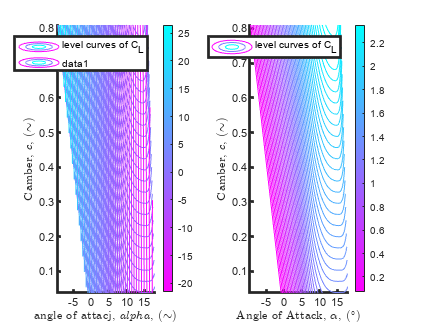


% vs alpha 
figure;
subplot(1,2,1); % Lift coefficient gradients
hold on;
contour(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), 50)
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient due to perabation in angle of attack, $C_{L_{\alpha}}$, $(\sim)$", "Interpreter","latex")
legend("level curves of C_L")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);

% coefficient of moment contour
contour(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), rad2deg(Moment_surface_mesh(:,:,3)), 50);
xlabel("angle of attacj, $alpha$, $(\sim)$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("moment Coefficient due to perabation in camber, $C_{M_{camb}}$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); cb = colorbar; ylabel(cb, 'Pitching Moment Coefficient, $C_M$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
colorbar;
set(gca,"LineWidth",2);

subplot(1,2,2); % Moment coefficient gradients
hold on;
%contour(rad2deg(Moment_surface_mesh(alpha_filter_tirm,:,1)), Moment_surface_mesh(alpha_filter_tirm,:,2), Moment_surface_mesh(alpha_filter_tirm,:,4)./Moment_surface_mesh(alpha_filter_tirm,:,3),50)
contour(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), 50);
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient due to perabation in camber, $C_{L_{camb}}$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
legend("level curves of C_L ");
colorbar;
set(gca,"LineWidth",2);

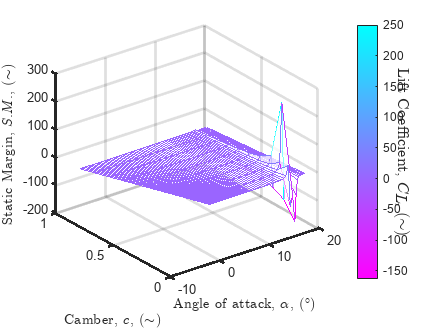



% plot the Static margin surface
figure;
mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), -C_M_alpha./C_L_alpha, "FaceAlpha",.5);
xlabel("Angle of attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Static Margin, $S.M.$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);

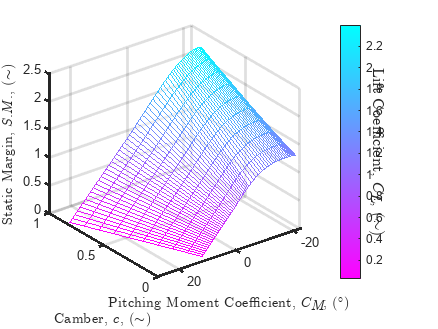



% C_L vs C_m where slope is S_M
figure;
%mesh(rad2deg(Moment_surface_mesh(:,:,3)), Moment_surface_mesh(:,:,2), -C_M_alpha./C_L_alpha, "FaceAlpha",.5);
mesh(rad2deg(Moment_surface_mesh(:,:,3)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), "FaceAlpha",.5);
xlabel("Pitching Moment Coefficient, $C_M$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Static Margin, $S.M.$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,'XDir','rev');
set(gca,"LineWidth",2);

## Make Camber a function of alpha

camber_1 = .81;
alpha_1 = deg2rad(-1);
camber_2 = .03767;
alpha_2 = deg2rad(16);

camber_c = .6;
alpha_c = deg2rad(6.97);

% C_M_1 = -.4181;
% C_M_2 = 

camberSlope = (camber_2 - camber_1) ./ (alpha_2 - alpha_1);
%camberSlope_mom = (camber_2 - camber_1) ./ (C_M_2 - C_M_1);
camberSlope = -.099 * 57

camberSlope = -5.6430

camberSlope = -.15 * 57

camberSlope = -8.5500

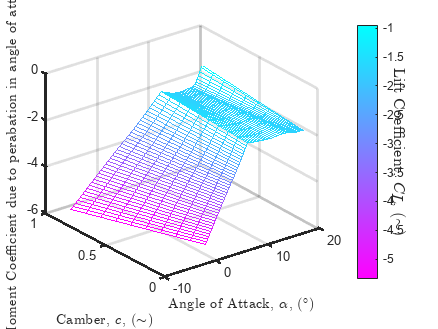



camber = @(alpha) camber_1 + camberSlope * (alpha-alpha_1);

dcamber_dalpha = @(alpha) diff(camber(alpha));

dc_M_dalpha = C_M_camber * camberSlope + C_M_alpha;
dc_L_dalpha = C_L_camber * camberSlope + C_L_alpha;


% plot the moment surface for a different camber slope
figure;
mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), dc_M_dalpha, "FaceAlpha",.5);
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Pitch Moment Coefficient due to perabation in angle of attack, $C_{m_{\alpha}}$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);

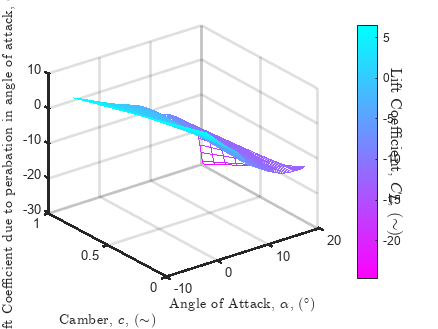


% plot the lift surface for a different camber slope
figure;
mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), dc_L_dalpha, "FaceAlpha",.5);
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Lift Coefficient due to perabation in angle of attack, $C_{L_{\alpha}}$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);

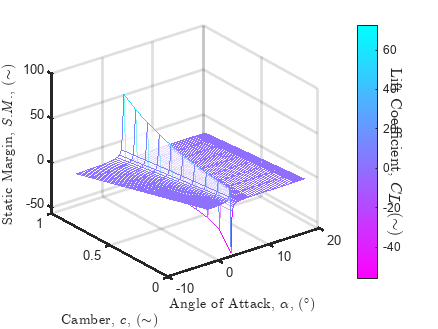


% plot the static margin surface for a different camber slope
figure;
mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), -dc_M_dalpha./dc_L_dalpha, "FaceAlpha",.5);
xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
zlabel("Static Margin, $S.M.$, $(\sim)$", "Interpreter","latex")
colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
set(gca,"LineWidth",2);

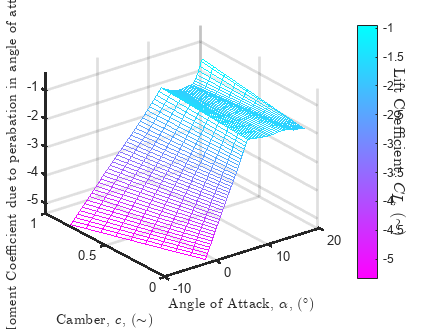



figure;
for cSlope = linspace(0,camberSlope, n_frames_animate)
    dc_M_da = C_M_camber * cSlope + C_M_alpha;
    mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), dc_M_da, "FaceAlpha",.5);
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Pitch Moment Coefficient due to perabation in angle of attack, $C_{m_{\alpha}}$, $(\sim)$", "Interpreter","latex")
    colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
    set(gca,"LineWidth",2);
    zlim([min(C_M_camber * camberSlope + C_M_alpha,[],"all"), max(C_M_alpha,[],"all")])
    drawnow;
end

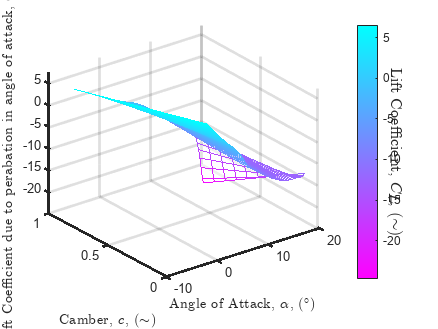


figure;
for cSlope = linspace(0,camberSlope, n_frames_animate)
    dc_L_da = C_L_camber * cSlope + C_L_alpha;
    mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), dc_L_da, "FaceAlpha",.5);
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Lift Coefficient due to perabation in angle of attack, $C_{L_{\alpha}}$, $(\sim)$", "Interpreter","latex")
    colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
    set(gca,"LineWidth",2);
    zlim([min(C_L_camber * camberSlope + C_L_alpha,[],"all"), max(C_L_alpha,[],"all")])
    drawnow;
end


figure;
for cSlope = linspace(0,camberSlope, n_frames_animate)
    dc_M_da = C_M_camber * cSlope + C_M_alpha;
    dc_L_da = C_L_camber * cSlope + C_L_alpha;
    SM = -dc_M_da./dc_L_da;
    mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), SM, "FaceAlpha",.5);
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Static Margin, $S.M.$, $(\sim)$", "Interpreter","latex")
    colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
    cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
    set(gca,"LineWidth",2);
    drawnow;
end

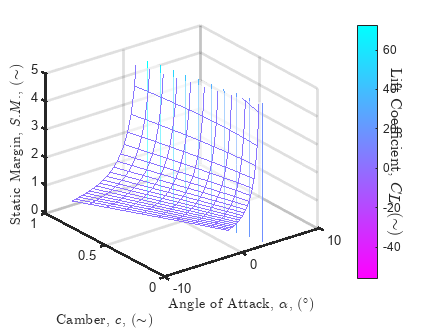


% static margin but htis time we will not go anywhere near stall
figure;
for cSlope = linspace(0,camberSlope, n_frames_animate)
    dc_M_da = C_M_camber * cSlope + C_M_alpha;
    dc_L_da = C_L_camber * cSlope + C_L_alpha;
    SM = -dc_M_da./dc_L_da;

    alpha_max = deg2rad(7);
    alpha_filter = Moment_surface_mesh(:,1,1) <= alpha_max;

    mesh(rad2deg(Moment_surface_mesh(alpha_filter,:,1)), Moment_surface_mesh(alpha_filter,:,2), SM(alpha_filter,:), "FaceAlpha",.5);
    set(gca,"LineWidth",2);
    colormap cool;
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
    zlabel("Static Margin, $S.M.$, $(\sim)$", "Interpreter","latex")
    colormap(flipud(cool)); cb = colorbar; ylabel(cb,'Lift Coefficient, $C_L$, $(\sim)$', "Interpreter","latex", 'FontSize',12,'Rotation',270);
    zlim([0,5]);
    %set(gca,'Color',[0 0 0],'GridColor',[1 1 1],'MinorGridColor',[1 1 1],'XColor',[1 1 1],'YColor',[1 1 1],'ZColor',[1 1 1]);
    drawnow;  
end

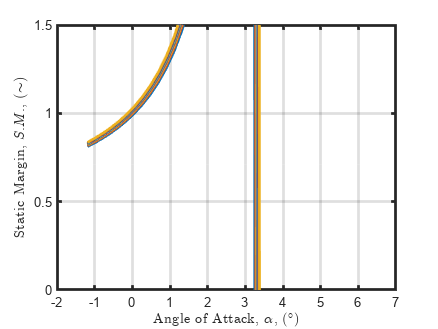



% static margin animation for single lift curve
figure;
for cSlope = linspace(0,camberSlope, n_frames_animate)
    dc_M_da = C_M_camber * cSlope + C_M_alpha;
    dc_L_da = C_L_camber * cSlope + C_L_alpha;
    SM = -dc_M_da./dc_L_da;

    alpha_max = deg2rad(7);
    alpha_filter = Moment_surface_mesh(:,1,1) <= alpha_max;

    plot(rad2deg(Moment_surface_mesh(alpha_filter,1,1)), SM(alpha_filter,:), "linewidth",2);
    set(gca,"LineWidth",2);
    colormap cool;
    grid on;
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Static Margin, $S.M.$, $(\sim)$", "Interpreter","latex");
    ylim([0,1.5]);
    xlim([-2,7]); ylim([0,1.5]);
    %set(gca,'Color',[0 0 0],'GridColor',[1 1 1],'MinorGridColor',[1 1 1],'XColor',[1 1 1],'YColor',[1 1 1],'ZColor',[1 1 1]);
    drawnow;  
end

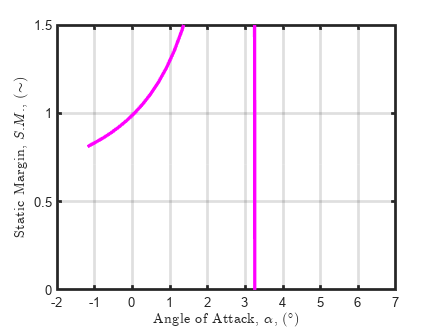


% static margin starting with neutral camaber
figure;
for cSlope = linspace(0,camberSlope, n_frames_animate)
    dc_M_da = C_M_camber * cSlope + C_M_alpha;
    dc_L_da = C_L_camber * cSlope + C_L_alpha;
    SM = -dc_M_da./dc_L_da;

    alpha_max = deg2rad(7);
    alpha_filter = Moment_surface_mesh(:,1,1) <= alpha_max;

    plot(rad2deg(Moment_surface_mesh(alpha_filter,1,1)), SM(alpha_filter,1), "-m", "linewidth",2.5);
    set(gca,"LineWidth",2);
    colormap cool;
    grid on;
    xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
    ylabel("Static Margin, $S.M.$, $(\sim)$", "Interpreter","latex")
    xlim([-2,7]); ylim([0,1.5]);
    % set(gca,'Color',[0 0 0],'GridColor',[1 1 1],'MinorGridColor',[1 1 1],'XColor',[1 1 1],'YColor',[1 1 1],'ZColor',[1 1 1]); set(gcf,'Color',[0 0 0]);
    drawnow;  
end



camber_c = .6;
alpha_c = deg2rad(7); % location of center of surface for renfrence plotting plane


% % 3D trim diagram with cutting plane
% figure;
% 
% cSlope = camberSlope;
% 
% 
% % Lift coefficient vs alpha
% ax1 = subplot(1,2,1);
% mesh(rad2deg(Moment_surface_mesh(:,:,1)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), "FaceAlpha",.5 , "FaceColor", "interp");
% xlabel("Angle of Attack, $\alpha$, $(^{\circ})$", "Interpreter","latex");
% ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
% zlabel("Lift Coefficient, $C_M$, $(\sim)$", "Interpreter","latex")
% 
% % Lift coefficient vs Moment coefficient
% ax2 = subplot(1,2,2);
% mesh(rad2deg(Moment_surface_mesh(:,:,3)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4), "FaceAlpha",.5 , "FaceColor", "interp");
% xlabel("Pitch Moment Coefficient, $C_M$, $(\sim)$", "Interpreter","latex");
% ylabel("Camber, $c$, $(\sim)$", "Interpreter","latex");
% zlabel("Lift Coefficient, $C_L$, $(\sim)$", "Interpreter","latex");
% linkaxes([ax1, ax2], 'yz');
% set(gca,'XDir','rev');
% 
% hold on
% Delta_C_M_ih = C_m_ih % for now assume linear ignore horizontal tail blanking
% p_ih = deg2rad(20);
% m_ih = deg2rad(-20);
% c_m_p_ih = arrayfun(@(alpha) integral(@(ih) arrayfun(@(i) PitchMomentCoefficient_withRespectTo_horizontalTailIncidence(S_h, get_eta_h(alpha, eta_FuncOf_alpha), C_L_alpha_h, x_bar_cg, x_bar_ac_h, S), ih), 0, p_ih), Moment_surface_mesh(:,1,1))
% c_m_m_ih = arrayfun(@(alpha) integral(@(ih) arrayfun(@(i) PitchMomentCoefficient_withRespectTo_horizontalTailIncidence(S_h, get_eta_h(alpha, eta_FuncOf_alpha), C_L_alpha_h, x_bar_cg, x_bar_ac_h, S), ih), 0, m_ih), Moment_surface_mesh(:,1,1))
% %c_L_p_ih = arrayfun(@(alpha) integral(@(alpha) arrayfun(@(i) (S_h/S*get_eta_h(alpha, eta_FuncOf_alpha))* C_L_alpha_h, 0, p_ih), 0, alpha), Moment_surface_mesh(:,1,1))
% 
% mesh(rad2deg(Moment_surface_mesh(:,:,3)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4) +  c_m_p_ih, "FaceAlpha",.5);
% mesh(rad2deg(Moment_surface_mesh(:,:,3)), Moment_surface_mesh(:,:,2), Moment_surface_mesh(:,:,4) +  c_m_m_ih, "FaceAlpha",.5);
% 
% 
% % plot the slicing plane
% 
% 
% %[alpha_slice, C_L_slice] = meshgrid(linspace(,, nSlicePoints), linspace(min(Moment_surface_mesh(:,:,3),[],"all"), max(Moment_surface_mesh(:,:,3),[],"all"), nSlicePoints));
% [alpha_slice, C_L_slice] = meshgrid(linspace(min(Moment_surface_mesh(:,:,1),[],"all"), max(Moment_surface_mesh(:,:,1),[],"all"), nSlicePoints), linspace(min(Moment_surface_mesh(:,:,4),[],"all"), max(Moment_surface_mesh(:,:,4),[],"all"), nSlicePoints));
% [C_M_slice, C_L_slice_mom] = meshgrid(linspace(min(Moment_surface_mesh(:,:,3),[],"all"), max(Moment_surface_mesh(:,:,3),[],"all"), nSlicePoints), linspace(min(Moment_surface_mesh(:,:,4),[],"all"), max(Moment_surface_mesh(:,:,4),[],"all"), nSlicePoints));
% camber_slice = camber_c + cSlope * C_M_alpha * (alpha_slice - alpha_c);
% slicePlane = mesh(C_M_slice, camber_slice, C_L_slice, "FaceAlpha",.5, "EdgeColor","none", "FaceColor",[.3,.3,.3]);
% 
% [alpha_slice, C_M_slice] = meshgrid(linspace(min(Moment_surface_mesh(:,:,1),[],"all"), max(Moment_surface_mesh(:,:,1),[],"all"), nSlicePoints), linspace(min(Moment_surface_mesh(:,:,3),[],"all"), max(Moment_surface_mesh(:,:,3),[],"all"), nSlicePoints));

% The old way to do eta h
% function eta_h = get_eta_h(alpha, eta_FuncOf_alpha)
%     for alpha_i = alpha
%         alpha_d = rad2deg(alpha_i);
%         if(alpha_d < 0) % find eta h from extrapolation
%             % create a polynamial fit to extrapolate from
%             eta_h_negative_poly = polyfit(eta_FuncOf_alpha(1:7,1), eta_FuncOf_alpha(1:7,2),1);
%             eta_h = polyval(eta_h_negative_poly, alpha_i); % find eta h from extrapolation
%     
%         elseif alpha_d < 24 % find eta h from intterpolation
%             index = find(eta_FuncOf_alpha(:,1) == deg2rad(floor(alpha_d))); % index of first vicinal point in array
%             %linear interpolate to get the value
%             eta_h = eta_FuncOf_alpha(index,2) + (eta_FuncOf_alpha(index+1,2) - eta_FuncOf_alpha(index,2)) / (eta_FuncOf_alpha(index+1,1) - eta_FuncOf_alpha(index,1)) * (alpha_i - eta_FuncOf_alpha(index,1));
%         else
%             fprintf("alpha: %g degrees not in acceptable range", alpha_d);
%         end
%     end
% end


function eta_h = get_eta_h(alpha, eta_FuncOf_alpha)
    % this one can be vecotrized implicitly
    % empircal equation using degrees thus convert rad->deg
    eta_h = ppval(eta_FuncOf_alpha, rad2deg(alpha));
    % adjust to accoutn for bias in the data
    eta_h = eta_h + .2;
end

function [Coefficient_alpha, Coefficient_camber] = MeshGradient(Coefficient, alphaMesh, camberMesh)
    % compute central diffence on center elements
    % initialize the deriviatve arrays
    Coefficient_alpha = zeros(size(Coefficient)); % initialize array
    Coefficient_camber = zeros(size(Coefficient)); % initialize array
    
    % compute deltas
    Delta_C_L_a_2 = Coefficient(3:end,:) - Coefficient(2:end-1,:);
    Delta_C_L_a_1 = Coefficient(2:end-1,:) - Coefficient(1:end-2,:);
    Delta_C_L_c_2 = Coefficient(:,3:end) - Coefficient(:,2:end-1);
    Delta_C_L_c_1 = Coefficient(:,2:end-1) - Coefficient(:,1:end-2);
    Delta_alpha_2 = alphaMesh(3:end,:) - alphaMesh(2:end-1,:);
    Delta_alpha_1 = alphaMesh(2:end-1,:) - alphaMesh(1:end-2,:);
    Delta_camber_2 = camberMesh(:,3:end) - camberMesh(:,2:end-1);
    Delta_camber_1 = camberMesh(:,2:end-1) - camberMesh(:,1:end-2);
    
    % compute central difference
    Coefficient_alpha(2:end-1,:) = (Delta_C_L_a_2./Delta_alpha_2 + Delta_C_L_a_1./Delta_alpha_1) / 2;
    Coefficient_camber(:,2:end-1) = (Delta_C_L_c_2./Delta_camber_2 + Delta_C_L_c_1./Delta_camber_1) / 2;
    
    % compute first order one side difference on edges
    Coefficient_alpha(1,:) = (Coefficient(2,:) - Coefficient(1,:)) ./  (alphaMesh(2,:) - alphaMesh(1,:));
    Coefficient_alpha(end,:) = (Coefficient(end,:) - Coefficient(end-1,:)) ./  (alphaMesh(end,:) - alphaMesh(end-1,:));
    Coefficient_camber(:,1) = (Coefficient(:,2) - Coefficient(:,1)) ./  (camberMesh(:,2) - camberMesh(:,1));
    Coefficient_camber(:,end) = (Coefficient(:,end) - Coefficient(:,end-1)) ./  (camberMesh(:,end) - camberMesh(:,end-1));
end

% depricated
function C_l_alpha = get_C_l_alpha(alpha, airfoil)
    C_l_alpha_linear = (airfoil.c_l_star - 0) ./ (airfoil.alpha_star - airfoil.alpha_0);
    C_l_alpha_nonlinear = (airfoil.c_l_max - airfoil.c_l_star) ./ (airfoil.alpha_c_l_max - airfoil.alpha_star);
    C_l_alpha_postStall = (airfoil.c_l_post_stall - airfoil.c_l_max) ./ (airfoil.alpha_post_stall - airfoil.alpha_c_l_max);

    % produce C_l_alpha as a peicwise constant funtion
    C_l_alpha = heaviside(-(alpha - airfoil.alpha_star)) .* C_l_alpha_linear + ...
        heaviside((alpha - airfoil.alpha_star)) .* heaviside(-(alpha - airfoil.alpha_c_l_max)) .* C_l_alpha_nonlinear + ...
        heaviside((alpha - airfoil.alpha_c_l_max)) .* heaviside(-(alpha - airfoil.alpha_post_stall)) .* C_l_alpha_postStall;
end

% gets the airfract pitching moment coeffcient
function C_m = PitchingMomentCoeffcient(alpha, i_h, C_m_0_wf, C_m_0_h, airfoil, C_L_alpha_h, x_bar_cg, x_bar_ac_wf, x_bar_ac_h, S_h, S, eta_FuncOf_alpha, d_epsilon_h_d_alpha)
    C_m = C_m_0_wf + C_m_0_h + arrayfun(@(alph) integral(@(a) PitchMomentCoefficient_withRespectTo_Alpha_wingFueslage(airfoil.get_C_l_alpha(a),x_bar_cg,x_bar_ac_wf) + PitchMomentCoefficient_withRespectTo_Alpha_horizontalTail(S_h, get_eta_h(a, eta_FuncOf_alpha), C_L_alpha_h, d_epsilon_h_d_alpha, x_bar_cg, x_bar_ac_h, S) + PitchMomentCoefficient_withRespectTo_horizontalTailIncidence(S_h,  get_eta_h(a, eta_FuncOf_alpha), C_L_alpha_h, x_bar_cg, x_bar_ac_h, S) * i_h, 0, alph), alpha);
end

function C_l = get_C_l(alpha, airfoil)
    C_l = (airfoil.c_l_0 + integral(@(a) airfoil.get_C_l_alpha(a), 0, alpha)) * heaviside(-(alpha -airfoil.alpha_post_stall));
end

function spl = CL_alpha_Smooother(four_points_matrix, plot_yn, n)
    %   Example:
    %       points = [-.174533, 0; .1396, 2.1; .2443, 2.4; .2793, 2.2];
    %       spl = generate_spline(points, true);
    %       n between 1 and 5, 5 being most linear in linear region (adds spline points on line to force the function)
    
    x_data = four_points_matrix(:,1)';
    y_data = four_points_matrix(:,2)';
    
    slope_at_point_one = (y_data(2) - y_data(1)) / (x_data(2) - x_data(1));
    
    %%%%%%%%%%%%%%%%%%%%%%%  Adjust linearity of linear region %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Calculate the step size for inserting the new points
    step_size = 1 / (n + 1);
    
    % Initialize arrays to store the new points
    new_x = zeros(1, n);
    new_y = zeros(1, n);
    
    % Calculate the coordinates of the new points
    for k = 1:n
        new_x(k) = (1 - k * step_size) * x_data(1) + k * step_size * x_data(2);
        new_y(k) = (1 - k * step_size) * y_data(1) + k * step_size * y_data(2);
    end
    
    % Insert new points into x_data and y_data
    x_data = [x_data(1), new_x, x_data(2:end)];
    y_data = [y_data(1), new_y, y_data(2:end)];
    
    %%%%%%%%%%%%%%%%%%%%%%%  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    err = 1; m_end = 1; i = 0; signn = 1; d_maximum = 1;
    while abs(err) > 10^-3 % changes end slope until point 3 slope is zero
        i = i + 1;
        err_old = d_maximum;
    
        slope_at_point_four = (y_data(4) - m_end * y_data(3)) / (x_data(4) - x_data(3)); % KEEP SCALING FACTOR m_end
        spl = csape(x_data, y_data, 'complete', [slope_at_point_one, slope_at_point_four]);
        d_maximum = ppval(fnder(spl), x_data(end-1));
    
    
        if d_maximum > 0
            m_end = m_end + signn*m_end * err * 10^-2;
        else
            m_end = m_end - signn*m_end * err * 10^-2;
        end
    
        err = d_maximum;
    
        if i > 500
            disp('error, no spline convergence')
            break
        end
    
        if mod(i, 2) == 0
            if abs(err_old) < abs(err)
                signn = signn*-1;
            end
        end
    
    
    
    end
    
    if nargin < 2
        plot_yn = true; % Default to plotting
    end
    
    if plot_yn
        x_interp = linspace(min(x_data), max(x_data), 1000);
        y_interp = fnval(spl, x_interp);
    
        % Plot the original data and the spline
        plot(x_data([1,end-2,end-1,end]), y_data([1,end-2,end-1,end]), 'ko', 'MarkerSize', 8);
        hold on;
        plot(x_data(2:end-3), y_data(2:end-3), 'r*', 'MarkerSize', 8);
        plot(x_interp, y_interp, '-', 'LineWidth', 1.5);        xlabel('alpha');
        ylabel('C_L');
    end
end